data_dir = getenv("DATA_DUSS");

subjstr = 'S01';
medstr= 'off';
task='move';


load_mat_file = 1;
load_fif_file = 0;
recalc_sim = 1;
recalc_srcrec = 1;
plot_true_dipole_loc = 1;
test_dataset_info = load(strcat(data_dir,"/S99_off_move_supp_info.mat"));

if load_mat_file
  basename_resampled = sprintf('/%s_%s_%s_resampled.mat',subjstr,medstr,task);
  fname_resampled = strcat(data_dir, basename_resampled);
  if ~isfile(fname_resampled)

    basename = sprintf('/%s_%s_%s.mat',subjstr,medstr,task);
    fname_mat = strcat(data_dir, basename );

    datall_mat = load(fname_mat);
    datall_mat = datall_mat.data;

    cfg_resample = [];
    cfg.resamplefs      = 256;
    if ~isfile(fname)
      cfg.outputfile = fname_resampled;
    end
    data_resampled = ft_resampledata(cfg, datall_mat);
  else
    data_resampled = load(fname_resampled);
    data_resampled = data_resampled.data;
  end
elseif load_fif_file
  basename = sprintf('/%s_%s_%s_resample_afterICA_raw.fif',subjstr,medstr,task);
  fname = strcat(data_dir, basename );

  cfgload = [];
  cfgload.dataset = fname;          % fname should be char array (single quotes), not string (double quotes)
  cfgload.chantype = {'meg'};
  cfgload.coilaccuracy = 1;   % 0 1 or 2, idk what each of them means
  datall_ = ft_preprocessing(cfgload);   
  data_resampled = datall_;
end


sgf = load([data_dir, sprintf('/headmodel_grid_%s_surf.mat',subjstr)] );
subject_surf_grid = sgf.mni_aligned_grid;  % in cm


basename_head = sprintf('/headmodel_grid_%s.mat',subjstr);
fname_head = strcat(data_dir, basename_head );
hdmf = load(fname_head);   %hdmf.hdm, hdmf.mni_aligned_grid


fn = strcat( subjstr, '_modcoord_parcel_aal.mat');
sprintf('Loading %s',fn)

ans = 'Loading S01_modcoord_parcel_aal.mat'

ff = load(fn);
srcpos = ff.coords_Jan_actual;

all_coords = ff.coords_Jan_actual;

roi_labels_with_tremor = fieldnames(test_dataset_info.roi_sensors);
%roi_labels_with_tremor = {'Supp_Motor_Area_R', 'Cerebellum_L'};
%roi_labels_with_tremor = {'Supp_Motor_Area_R'};
%roi_labels_with_tremor = {'Cerebellum_L'};
src_coords = zeros(0,3);
srcinds = [];
for roi_lab_ii=1:length(roi_labels_with_tremor)
  lab_cur = roi_labels_with_tremor{roi_lab_ii};
  roii = find(strcmp(ff.labels, lab_cur ) );
  srcinds_cur = find(ff.point_ind_corresp == roii);
  srcinds = [srcinds;srcinds_cur];
  fprintf('%s %d\n',lab_cur,length(srcinds_cur) );
  %src_coords_cur = all_coords(srcinds_cur,:);
  %src_coords = [src_coords;src_coords_cur];
end

Supp_Motor_Area_R 5
Cerebellum_L 36



src_coords  = all_coords(srcinds,:);


%src_coords = src_coords(1,:);
[sz1,sz2] = size(src_coords);

times = data_resampled.time{1};
size(src_coords)

ans =     41     3


dip_dir = [0 1 1];
sfreq = cast(test_dataset_info.sfreq, 'double');

cfg_sim = [];
cfg_sim.headmodel = hdmf.hdm;
cfg_sim.grad = data_resampled.grad;
cfg_sim.fsample = sfreq;
cfg_sim.numtrl = 1;
%time_duration = 150;

time_duration = cast(test_dataset_info.total_duration, 'double');
cfg_sim.trllen = time_duration;
cfg_sim.dip.pos = src_coords;  % I am not sure it has any influence
%cfg_sim.dip.mom = 10 * repmat( dip_dir, sz1, 1)' ;   % the dipole points along the x-axis
cfg_sim.dip.mom = src_coords + [5 0 0];  % this way reconstruction works weirdly --
%I don't see corresponding frequencies in the result
times_for_sim = ( 1:(sfreq*time_duration) ) / sfreq;
lowfreq = 1;
highfreq = cast(test_dataset_info.trem_burst_meg_freq, 'double');

bl = 0;
ampl = 0.3;
start_time = 8

start_time = 8


modulated_signal = sin(times_for_sim * 2 * pi * highfreq);
signal_common = modulated_signal;
%modulation = sin(times_for_sim * 2 * pi * lowfreq) ;
%modulation = heaviside(times_for_sim - start_time) ;
modulation = test_dataset_info.tremor_intensity;
signal_common = bl + ampl * signal_common .* modulation

signal_common =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


signals = repmat(signal_common, sz1, 1);

cfg_sim.dip.signal  = {signals};
%ts = cell(length(src_coords),1);
ts = {times_for_sim};
cfg_sim.dip.time = ts;
%cfg_sim.relnoise = 10;
%cfg_sim.dip.frequency = 30;
%cfg_sim.dip.amplitude = 10;
%   cfg.fsample    = simulated sample frequency (default = 1000)
%   cfg.trllen     = length of simulated trials in seconds (default = 1)
%   cfg.numtrl     = number of simulated trials (default = 10)
%   cfg.baseline   = number (default = 0.3)
cfg_sim.relnoise = 0.5;  %10 is a lot %3 is ok-ish  0.3% too little
cfg_sim.relnoise = 3;  %10 is a lot %3 is ok-ish  0.3% too little
cfg_sim.ntrials = 1;
data_simulated = ft_dipolesimulation(cfg_sim);

 In ft_checkconfig at line 130
 In ft_dipolesimulation at line 111

using gradiometers specified in the configuration
computing surface normals
computing data data
computing data data for trial 1

RMS value of data data is 9.47587e-10
the call to "ft_dipolesimulation" took 1 seconds and required the additional allocation of an estimated 64 MB




save( [data_dir,sprintf('/%s_%s_%s_MEGsim.mat','S99',medstr,task)], "data_simulated","-v7.3" );

cfg_tla = [];
cfg_tla.covariance = 'yes';
tlout = ft_timelockanalysis(cfg_tla,data_simulated);

the input is raw data with 306 channels and 1 trials


 In fixsampleinfo at line 88
 In ft_datatype_raw at line 149
 In ft_checkdata at line 267
 In ft_timelockanalysis at line 101



 In fixsampleinfo at line 101
 In ft_datatype_raw at line 149
 In ft_checkdata at line 267
 In ft_timelockanalysis at line 101

> In fixsampleinfo (line 102)
  In 



cfg = [];
%cfg.xlim = [0.3 0.5];
%cfg.zlim = [0 6e-14];
cfg.layout = 'neuromag306all.lay';
cfg.layout = 'neuromag306all_helmet.mat';
%cfg.parameter = 'individual'; % the default 'avg' is not present in the data
figure; ft_topoplotER(cfg,tlout); colorbar; 

reading layout from file neuromag306all_helmet.mat
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_topoplotER" took 1 seconds and required the additional allocation of an estimated 1 MB


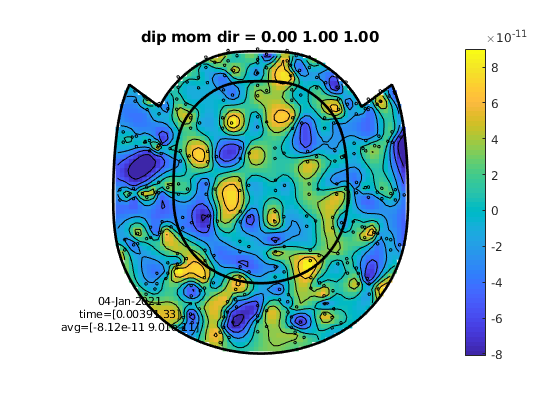

aa = sprintf("dip mom dir = %.2f %.2f %.2f",dip_dir(1), dip_dir(2), dip_dir(3));
title(aa)

 

sensor_inds = cell(length(roi_labels_with_tremor));
for ii = 1:length(roi_labels_with_tremor)
    sensor_inds{ii} = test_dataset_info.roi_sensors.(roi_labels_with_tremor{ii});
end


figure();
si = 1

si = 1

xlims = [6,11]

xlims =      6    11



for i = 1:length(sensor_inds)
    subplot(3,1,si); 
    hold on
    for ii = 1:length(sensor_inds{i})
        plot(times_for_sim, data_simulated.trial{1}(sensor_inds{i}(ii),:));
    end
    xlim(xlims);  title(roi_labels_with_tremor{i});
    hold off
    si = si+1
end

si = 2

si = 3

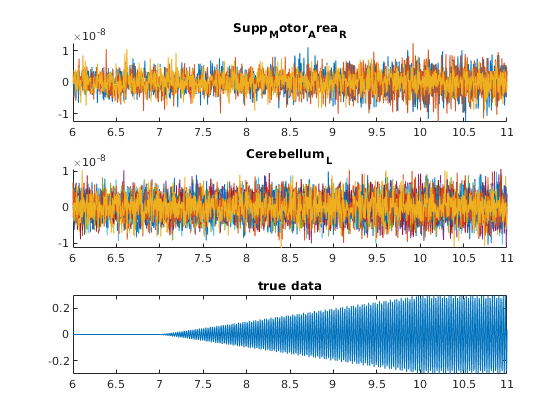


subplot(3,1,si); 
plot(times_for_sim, signal_common);
xlim(xlims);  title('true data');

use_rest_cov = 1

use_rest_cov = 1


rest_thr = 1e-5;
rest_thr = 0.1;
bins_bad = find(modulation > rest_thr );
bins_artif = zeros(1,2);
bins_artif(1,:) = [bins_bad(1) length(modulation)];
cfg_ar = [];
cfg_ar.artfctdef.imported.artifact = bins_artif;
cfg_ar.artfctdef.reject          = 'partial';
data_rest = ft_rejectartifact(cfg_ar,data_simulated);

 In fixsampleinfo at line 88
 In ft_datatype_raw at line 149
 In ft_checkdata at line 267
 In ft_rejectartifact at line 202



 In fixsampleinfo at line 101
 In ft_datatype_raw at line 149
 In ft_checkdata at line 267
 In ft_rejectartifact at line 202

> In fixsampleinfo (line 102)
  In 


cfg_tla = [];
cfg_tla.covariance = 'yes';
tlout_rest = ft_timelockanalysis(cfg_tla,data_rest);

the input is raw data with 306 channels and 1 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_timelockanalysis" took 0 seconds and required the additional allocation of an estimated 0 MB




tlout_to_use = tlout;
if use_rest_cov
    tlout_to_use = tlout_rest;
    r = srcrec(subjstr,data_simulated,data_rest,hdmf,"parcel_aal",[],[],[],[],0);
    source_time_tmp = r{1}.source_data;
else
    eigval = eig(tlout_to_use.cov);
    lambda = max(eigval) * 0.001;
    
    
    cfg_srcrec=[];
    cfg_srcrec.method='lcmv';
    cfg_srcrec.headmodel=hdmf.hdm;
    cfg_srcrec.sourcemodel = [];
    cfg_srcrec.sourcemodel.pos = all_coords;
    %cfg_srcrec.resolution = 2;
    %cfg_srcrec.supchan = bads;
    
    %cfg_srcrec.lcmv.lambda='5%';
    cfg_srcrec.lcmv.lamba = [num2str(lambda),'%']; %regularization value. Can be changed by inspection
    
    cfg_srcrec.lcmv.keepfilter = 'yes';
    cfg_srcrec.lcmv.projectmom='yes';
    %cfg_srcrec.lcmv.reducerank=2;  % always like that for MEG
    cfg_srcrec.lcmv.projectnoise = 'yes'; % needed for neural activity index
    %cfg.resolution = 1;
    
    
    %cfg.resolution = 1;
    %cfg.method = 'lcmv';
    
    source_time_tmp = ft_sourceanalysis(cfg_srcrec,tlout_to_use);  
    source_time_tmp_d = source_time_tmp;
end

data_cleaned = struct with fields:
          grad: [1×1 struct]
       fsample: 256
         label: {306×1 cell}
           cfg: [1×1 struct]
           hdr: [1×1 struct]
         trial: {[306×1869 double]}
          time: {[1×1869 double]}
    sampleinfo: [1 1869]


ans = 'Loading S01_modcoord_parcel_aal.mat'

the input is raw data with 306 channels and 1 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_timelockanalysis" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is timelock data with 306 channels and 1869 timebins
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
computing the leadfields on the fly
using gradiometers specified in the data
computing surface normals
creating sourcemodel based on user specified dipole positions
using gradiometers specified in the configuration
567 dipoles inside, 0 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds and required the additional allocation of an estimated 0 MB
scanning repetition 1
computing forward model on the fly
scanning grid
scanning grid 567/567

t


cfg = [];
cfg.powmethod = 'none'; % keep the power as estimated from the data covariance, i.e. the induced power
%cfg.powmethod = 'pow'; 
source_nai = ft_sourcedescriptives(cfg, source_time_tmp);

the call to "ft_sourcedescriptives" took 0 seconds and required the additional allocation of an estimated 0 MB


fband_cur = [-1 -1];
resEntry = [];
resEntry.source_data = source_time_tmp;
resEntry.bpfreq = fband_cur;
source_data = {resEntry};

roicur = 'parcel_aal';
for fbi = 1:length(resEntry) 
    source_data{fbi}.source_data.roi = {roicur};
end

save_srcrec=1;
if save_srcrec
    basename_srcd = sprintf("/srcd_%s_%s_%s_%s.mat",'S99',medstr,task,roicur);
    fname_srcd = strcat(data_dir, basename_srcd );
    fprintf("Saving to %s\n",fname_srcd)
    save(fname_srcd,"source_data","-v7.3");
end

Saving to /home/demitau/data/srcd_S99_off_move_parcel_aal.mat



source_time_tmp = r{1}.source_data;
[s1, s2] = size(source_time_tmp.avg.mom);
ss = cell(s1,1);
for ind=1:s1
    ss{ind} = source_time_tmp.avg.mom(ind,:);
end
source_time_tmp.avg.mom = ss;

mrun_plot_sources

nplots_sens = 1

si = 5

si = 6

class(zeros(3,3))

ans = 'double'

cfg              = [];

nplots_sens = 1

si = 5

si = 6

cfg.output       = 'pow';
cfg.channel      = 'MEG';
cfg.method       = 'mtmconvol';
cfg.taper        = 'hanning';
cfg.foi          = 20:2:40;                         % analysis 2 to 30 Hz in steps of 2 Hz
cfg.t_ftimwin    = ones(length(cfg.foi),1).*2;   % length of time window = 2 sec
cfg.toi          = -0.5:0.5:20;                  % time window "slides" from -0.5 to 1.5 sec in steps of 0.05 sec (50 ms)
TFRhann = ft_freqanalysis(cfg, data_simulated);


cfg = [];

fname_bads_mat = 'S01_off_move_MEGch_bads_upd.mat'

%cfg.baseline = [-0.5 -0.1];

fname_bads_mat_full = '/home/demitau/data/S01_off_move_MEGch_bads_upd.mat'

%cfg.zlim = [-3e-27 3e-27];

Error using load
Unable to read file '/home/demitau/data/S01_off_move_MEGch_bads_upd.mat'. No such file or directory.

cfg.baselinetype = 'absolute';
cfg.layout = 'neuromag306all.lay';
figure; ft_multiplotTFR(cfg,TFRhann)

cfg = [];
%cfg.method = 'ortho','surface','glassbrain' seem to require MRI anatomy 
%cfg.method = 'vertex';  % or cloud
cfg.method = 'cloud';  % or cloud
%cfg.cloudtype = 'point'; cfg.radius = 10;
%cfg.method = 'vertex';  % or cloud
cfg.funparameter = 'nai';
cfg.funcolormap = 'hot';
%cfg.funparameter = 'pow';
me = mean(source_nai.avg.nai);
mx = max(source_nai.avg.nai);
cfg.funcolorlim = [me (me + (mx-me)/2) ];  % the voxel in the center of the volume conductor messes up the autoscaling
cfg.funcolorlim = [me (mx - (mx-me)/4) ];  
span = (mx-me);
cfg.funcolorlim = [ (me + span/2) (mx + span/3) ];  
cfg.funcolorlim = [ me (mx + span/3) ];  
ft_sourceplot(cfg, source_nai);

view([40,180,200]);

mean(source_nai.avg.nai)
max(source_nai.avg.nai)

figure;
ft_plot_sens(data_resampled.grad, 'chantype', 'meggrad')
ft_plot_axes(data_resampled.grad)
view(-90, 90)

cfg = [];
cfg.layout = 'neuromag306all_helmet.mat'; % note that it is a binary .mat file, not an ASCII .lay file
cfg.layout = ft_prepare_layout(cfg);
%reading layout from file CTF151_helmet.mat
%the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 4 MB
figure; ft_plot_layout(cfg.layout);

t = tiledlayout(2,2,'TileSpacing','Compact','Padding','Compact');
nexttile
plot([0 1])

source_time_tmp.avg
source_time_tmp.avg.mom
source_nai.avg

fname_bads_mat = sprintf('%s_MEGch_bads_upd.mat','S01_off_move')
fname_bads_mat_full = [ data_dir, '/', fname_bads_mat]
bads_upd = load(fname_bads_mat_full)